# Solving Second order ODE with Non-homogeneous dirichlet BCs using Galerkin's Method. (Example 3)

Sagar Bodkhe

1/05/2020

__________________________________________________________________________________

In this example we are solving,

$\frac{d^2 u}{{\mathit{dx}}^2 }+\frac{\mathit{du}}{\mathit{dx}}+f\left(x\right)=0\;\;$ in $x\in \left\lbrack 0\;L\right\rbrack$

Boundary conditions: $u\left(0\right)=C\;;\;u\left(L\right)=D$

We intend to find out $u\left(x\right)$such that boundary conditions are satisfied.

Declare the symbolic variable. **Note**: The argument of the function are automatically declared as symbolic variable.

close all;
clear all;

% Declare symbolic variable
syms u(x); % the state variable
syms f(x); % function in DE
syms As(i0,j0); % The Matrix A
syms bs(i0); % Matrix b
syms psi(x,i0); % basis functions
syms psidd(x,i0); % second derivative of basis functions
syms psid(x,i0); % first derivative of basis functions
syms x
 assume(i0,'real')
assume(j0,'real')
assume(i0>0)
assume(j0>0)

Let us first find out the exact solution of the DE. We will use symbolic solver for this simple ODE.

% Define the function
f(x) = x^3 -2*x^2 + sin(x/3) +x;


% Define the ODE
ode = diff(u,x,2) + diff(u,x,1) == -f;

% Boundary Conditions
L=4; % Length of the domain
C=5;
D=-2;
cond1 = u(0) == C;
cond2 = u(L) == D;
conds = [cond1 cond2];
uSol(x) = dsolve(ode,conds);


Let us choose the dimesion of the trial space (same as the number of basis functions to be used) and select the basis function. The basis function should satisfy the essential boundary conditions.

N=8 ;% Dimension of trial space


% Generate Basis Functions and required derivative


The basis functions that we are choosing are: 

##  $\psi_i =\mathrm{sin}\left(i\frac{\pi x}{L}\right)$. 

Note that all of them satisfy essential BCs.

The other matrices/vectors :

psi(x,i0)= (sin(i0*x*pi/L)); % Basis functions 
psid(x,i0) = (diff(psi,x,1)); % first derivatives
psidd(x,i0) = (diff(psid,x,1));

bs(i0) = int(-(f+((D-C)/L))*psi(x,i0),x,[0 L]); %
As(i0,j0) = int(psi(x,i0)*(psid(x,j0)+psidd(x,j0)),x,[0 L]);

The above symbolic functions are single functions of i and j.

Now, let us generate the **A **and **b** matrices using nested for loop over **i** and **j**

A = zeros(N,N);
b = zeros(N,1);
 for i1=1:N
     for j1=1:N
        A(i1,j1)=double(As(i1,j1)); 
        % double used to convert to number from symbolic variable
     end
     b(i1) = double(bs(i1));
 end
 

Solving for the N coefficients (c)  $c=A^{-1} b$


% The coeff vector for system
c=A\b; 


We now have the c. We just need to plug-in the c into the appozimate solution that we constructed:

## 
$$u_h \left(x\right)=\sum_i c_{i\;} \psi_i \left(x\right)$$


For this let us first transform the **psi** and **psidd** symbolic function to a matlab function of two variables.



divs=100; % Number of divisions for domain for plotting
X = linspace(0,L,divs); % Define the domain

ps = zeros(divs,N);
psdd = zeros(divs,N); 
psd = zeros(divs,N); 
% Matrix whose each column con
% tain value of a basis function/derivative over the domain

for i2=1:N    
    ps(:,i2) = double(psi(X,i2));   
    psdd(:,i2) = double(psidd(X,i2));
    psd(:,i2) = double(psid(X,i2));
end

psdd(isnan(psdd))=psdd(2,1); % Correction for 0 to the power 0


U= (C + ((D-C)/L).*X)+ c'*ps'; % Trial Soltution
R= c'*psdd' + c'*psd'+ double(f(X));
R=round(R,7);


Let's plot the results now.

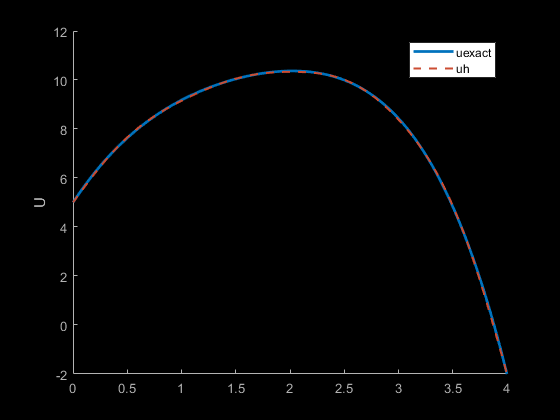

% Ploting Actual Solution and Trial solution
figure(1)
clf
hold on;

plot(X,double(uSol(X)),"Linewidth",2)
plot(X,U,'--',"Color",[0.8 0.3 0.2],"Linewidth",1.5)
ylabel("U")
legend("uexact","uh")



blackFig;

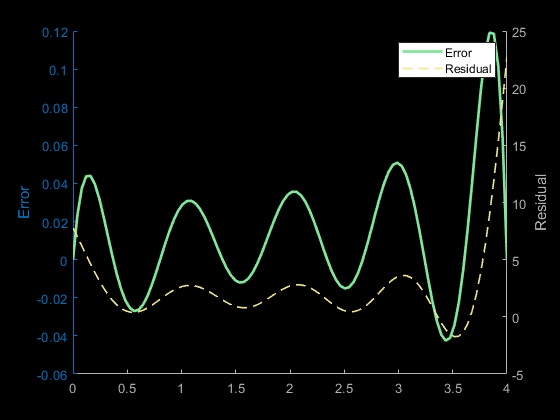


% Plotting Error
figure(2)
clf
hold on;

yyaxis left
ylabel("Error")
error = double((uSol(X)-U));
plot(X,round(error,7),'-',"Linewidth",2,"Color",[0.5 0.9 0.6])

yyaxis right
ylabel("Residual")
plot(X,R,'--',"Linewidth",1.2,"Color",[ 0.9412 0.9020 0.5490]);
legend("Error","Residual")

blackFig;